# SEL0459 - Controle Digital - SEL/EESC/USP

### Lista 07 - Espaço de Estados - Parte 01

#### Prof. Dr. Marcos Rogério Fernandes

**Aluno:** Vitor Augusto Tibério - 14658834

## Atividade 01 - Equivalente Discreto

clear all;
close all;
clc 

Definindo as matrizes A e B: 

A = [3 0 0;...
     5 4 0;...
     1 2 3];
B = [0 2 5]';

Encontrando o equivalente discreto (maneira manual):

Ts = 0.5;
Ad=expm(A*Ts)

Ad =     4.4817         0         0
   14.5368    7.3891         0
    8.9061    5.8147    4.4817


Bd=A\(Ad-eye(size(Ad)))*B

Bd =          0
    3.1945
    7.5496


Encontrando usando o c2d:

[Ad2,Bd2]=c2d(A,B,Ts)

Ad2 =     4.4817   -0.0000         0
   14.5368    7.3891         0
    8.9061    5.8147    4.4817


Bd2 =    -0.0000
    3.1945
    7.5496


## Atividade 02 - Estabilidade Assintótica

clear all 
close all
clc

Definindo a matriz Ad:

Ad = [0.75 -0.25 4;...
      2.25 -0.75 0;...
      -0.375 0.125 3.5];

Um modelo é assintitcamente estável se os autovalores da matriz de dinamica Ad estiverem dentro do círculo unitario. Logo, temos:

autovalores = eig(Ad)

autovalores =     0.0000
    0.5000
    3.0000


if any(abs(eig(Ad))>=1) %verifica se existe algum autovalor maior que 1
    disp('Sistema não e assintoticamente estável! =(')
else
    disp('Sistema é assintoticamente estável! =)')
end

Sistema nao e assintoticamente estavel!


Outro método que pode ser utilizado é a equação de Lyapunov, presente no código abaixo:

Q=eye(size(Ad))

Q =      1     0     0
     0     1     0
     0     0     1


P=dlyap(Ad,Q) %obtem solucao da eq. de lyapunov

P =    58.0885   76.4531   14.9115
   76.4531   84.6719   28.5469
   14.9115   28.5469    0.9635


if any(eig(P)<=0) %verifica se P>0
    disp('Sistema não é assintoticamente estavel! =(')
else
    disp('Sistema é assintoticamente estavel! =)')
end

Sistema nao e assintoticamente estavel!


## Atividade 03 - Modelos em Espaço de Estados Discreto

close all 
clear all
clc

Definindo as matrizes A e B: 

A = [-2 1 0;...
     0 -1 0;...
     0 0 -3];
B = [1 1 1]';

Definindo a discretização do tempo:

Ts=0.3;
T=5;
td=0:Ts:T;
dt=0.001;
t=0:dt:T;

Definindo o modelo em tempo contínuo e discreto: 

[Ac,Bc]=c2d(A,B,dt); %modelo tempo continuo (aproximacao)
[Ad,Bd]=c2d(A,B,Ts); %modelo em tempo discreto

Definindo as matrizes e variáveis auxiliares: 

Nd=numel(td);
Nc=numel(t);
n=size(Ad,1);
x=zeros(n,Nc);
xd=zeros(n,Nd);
u=ones(Nd,1);
xd(:,1)=[10 15 -5];
x(:,1)=xd(:,1);

Simulando o sistema: 

Nr=Ts/dt;
kd=1;
for k=1:Nc-1
    %% simula sistema em tempo continuo
    x(:,k+1)=Ac*x(:,k)+Bc*u(kd);
    %% simula sistema em tempo discreto
    if mod(k,Nr)==0 && kd<=numel(td)
        xd(:,kd+1)=Ad*xd(:,kd)+Bd*u(kd);
        kd=kd+1;
    end
end

Plotando os Gráficos:

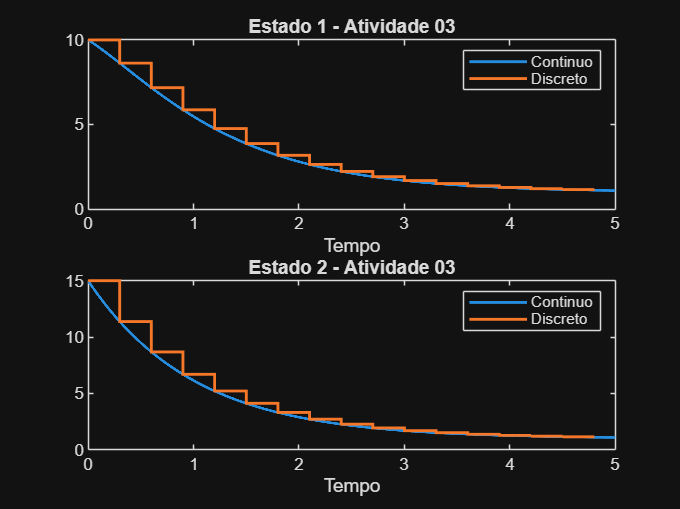

figure
subplot(2,1,1)
plot(t,x(1,:),'LineWidth',1.5)
hold on
stairs(td,xd(1,:),'LineWidth',1.5)
xlabel('Tempo')
legend('Continuo','Discreto')
title('Estado 1 - Atividade 03')
subplot(2,1,2)
plot(t,x(2,:),'LineWidth',1.5)
hold on
stairs(td,xd(2,:),'LineWidth',1.5)
xlabel('Tempo')
legend('Continuo','Discreto')
title('Estado 2 - Atividade 03')

## Atividade 04 - Parâmetros do Pêndulo Invertido

Obtendo as matrizes linearizadas para o sistema: 

close all
clear all
clc

Definindo as EDOs que modelam o sistema: 

syms m M l F g
syms th th_d th_dd
syms x x_d x_dd

eq1 = (M + m)*x_dd - m*l*th_dd*cos(th) + m*l*th_d^2*sin(th) - F;
eq2 = l*th_dd - x_dd*cos(th) - g*sin(th);
u = F;

S = solve(eq1 == 0, eq2 == 0, x_dd, th_dd);

Definindo o vetor X e X' (que é o vetor derivada)

x_vet = [x; x_d; th; th_d];
x_vet_dot = [x_d; S.x_dd; th_d; S.th_dd];

A = simplify(jacobian(x_vet_dot, x_vet));
B = simplify(jacobian(x_vet_dot, u));

Definindo o ponto de operação:

x = -1;
x_d = 0;
th = pi;
th_d = 0;
u = 0; 
F = 0;

A0 = simplify(subs(A));
B0 = simplify(subs(B));

M = 1;
m = 0.1;
l = 0.4;
g = 9.81;

A0 = double(simplify(subs(A)));
B0 = double(simplify(subs(B)));

Encontrando o equivalente discreto: 

Ts = 0.1

Ts = 0.1000

[Ad,Bd]=c2d(A0,B0,Ts)

Ad =     1.0000    0.1000    0.0048    0.0002
         0    1.0000    0.0937    0.0048
         0         0    0.8681    0.0956
         0         0   -2.5781    0.8681


Bd =     0.0050
    0.0996
   -0.0122
   -0.2389


Verificando se o modelo é assintoticamente estável: 

autovalores = eig(Ad)

autovalores =    1.0000 + 0.0000i
   1.0000 + 0.0000i
   0.8681 + 0.4964i
   0.8681 - 0.4964i


if any(abs(eig(Ad))>=1) %verifica se existe algum autovalor maior que 1
    disp('Sistema não e assintoticamente estável! =(')
else
    disp('Sistema é assintoticamente estável! =)')
end

Sistema não e assintoticamente estável! =(


Resposta: Para ambos, o sistema não é assintoticamente estável.  